clearvars
close all

## define stuff

path = "file_000.dat";      % data to load
chNum = 6;                  % number of channels to be read
tUnit = 1/1.25*10^-3;         % time per datapoint [s]
dt = 0.01;                  % signal edge addon [s]

## load and rearange data

fid = fopen("C:\temp\test_8\test_000.dat", "rb");
d = fread(fid, inf, "single");
data(1,:) = d(1:chNum:end);
data(2,:) = d(2:chNum:end);
data(3,:) = d(3:chNum:end);
data(4,:) = d(4:chNum:end);
data(5,:) = d(5:chNum:end);
data(6,:) = d(6:chNum:end);
t = (1:length(data))*tUnit;

## smart X

xLimStart = 178.65e3;
xLimEnd = 179.2e3;
%xFirst = min(find(data(5,:),1,'first'), find(data(6,:),1,'first'))*tUnit-dt;
%xLast = max(find(data(5,:),1,'last'), find(data(6,:),1,'last'))*tUnit+dt;

## plot stuff

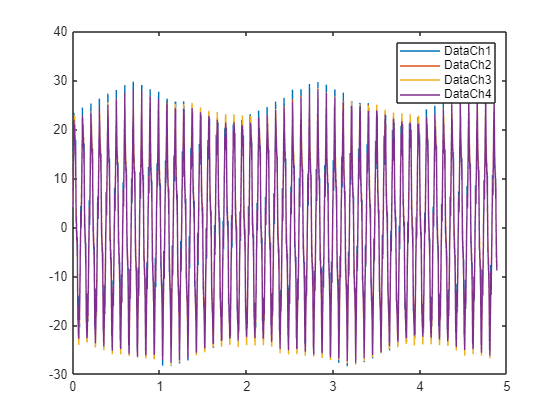

figure
plot(t, data(1,:)), hold on
plot(t, data(2,:)), hold on
plot(t, data(3,:)), hold on
plot(t, data(4,:))
legend('DataCh1', 'DataCh2', 'DataCh3', 'DataCh4')

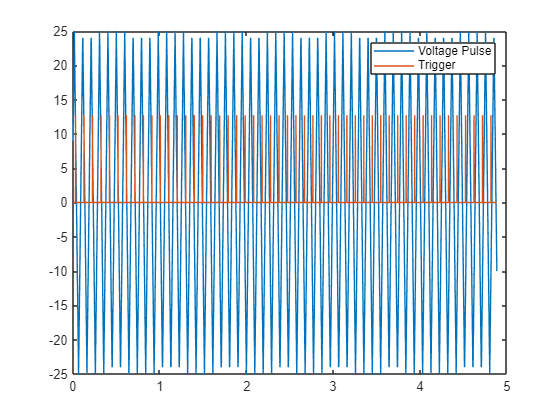

%xlim([0, 5])
%xlim([xFirst, xLast])
figure
plot(t, data(6,:)), hold on
plot(t, abs(data(5,:)*max(data(6,:)*250/3)))
legend('Voltage Pulse', 'Trigger')

%xlim([0, 5])
%xlim([xFirst, xLast])